syms w

M=[1 0 0;0 4 0;0 0 0.5]

M =     1.0000         0         0
         0    4.0000         0
         0         0    0.5000


K=[20 -10 0; -10 14 -4; 0 -4 4]

K =     20   -10     0
   -10    14    -4
     0    -4     4



K_dyn=(-M*w^2+K);
H=vpa(simplify(inv(K_dyn)),4)

$$H = \begin{array}{l} \left(\begin{array}{ccc} -\frac{1.0\,\left(2.0\,w^{4}-23.0\,w^{2}+40.0\right)}{\sigma_{3}} & \sigma_{2} & -\frac{40.0}{\sigma_{3}}\\ \sigma_{2} & -\frac{0.5\,\left(w^{2}-8.0\right)\,\left(w^{2}-20.0\right)}{\sigma_{3}} & \sigma_{1}\\ -\frac{40.0}{\sigma_{3}} & \sigma_{1} & -\frac{2.0\,\left(2.0\,w^{4}-47.0\,w^{2}+90.0\right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4.0\,\left(w^{2}-20.0\right)}{\sigma_{3}}\\ \sigma_{2}=\frac{5.0\,\left(w^{2}-8.0\right)}{\sigma_{3}}\\ \sigma_{3}=2.0\,w^{6}-63.0\,w^{4}+450.0\,w^{2}-400.0 \end{array}$$

assume(w,'Positive')
w=solve(det(-M*w^2+K)==0)

$$w = \left(\begin{array}{c} \sqrt{\mathrm{root}\left(z^{3}-\frac{63\,z^{2}}{2}+225\,z-200,z,1\right)}\\ \sqrt{\mathrm{root}\left(z^{3}-\frac{63\,z^{2}}{2}+225\,z-200,z,2\right)}\\ \sqrt{\mathrm{root}\left(z^{3}-\frac{63\,z^{2}}{2}+225\,z-200,z,3\right)} \end{array}\right)$$

vpa(w,2)

$$ans = \left(\begin{array}{c} 1.0\\ 3.0\\ 4.6 \end{array}\right)$$

i = 1

j = 1

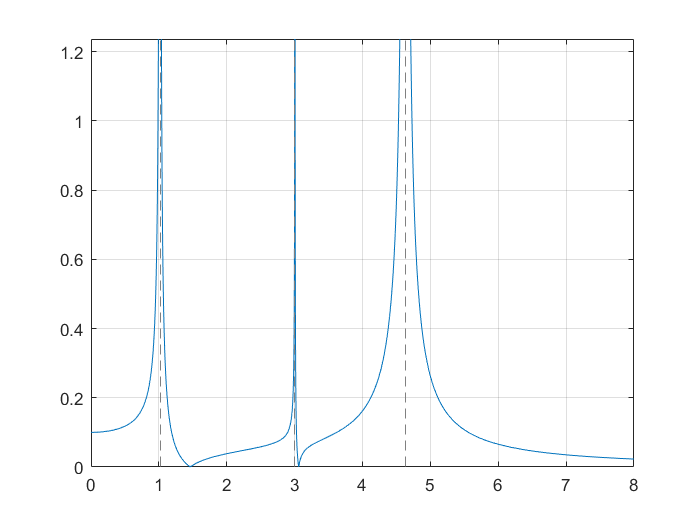

i = 1

j = 2

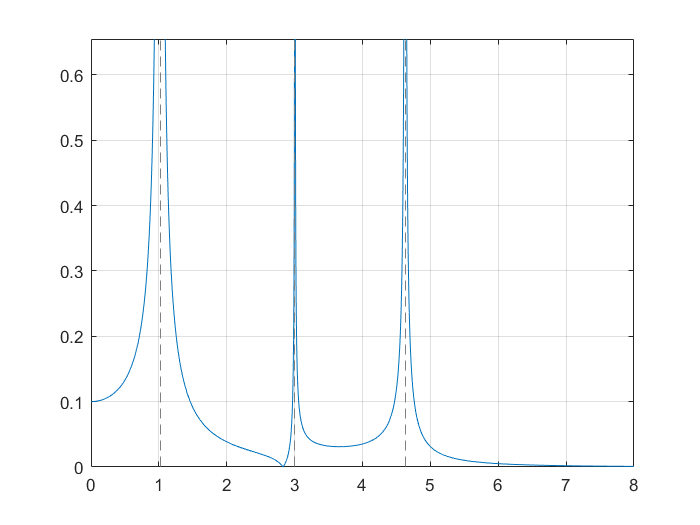

i = 1

j = 3

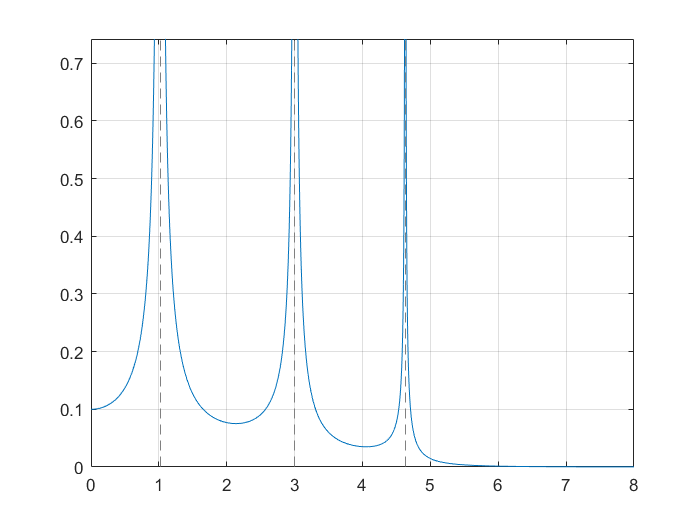

i = 2

j = 1

i = 2

j = 2

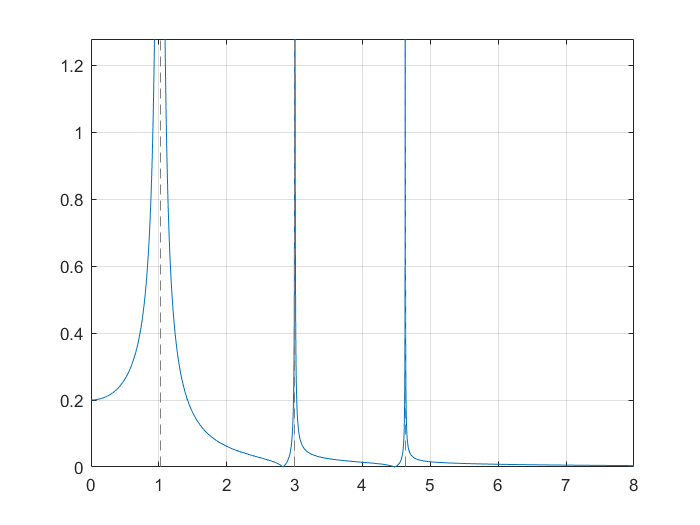

i = 2

j = 3

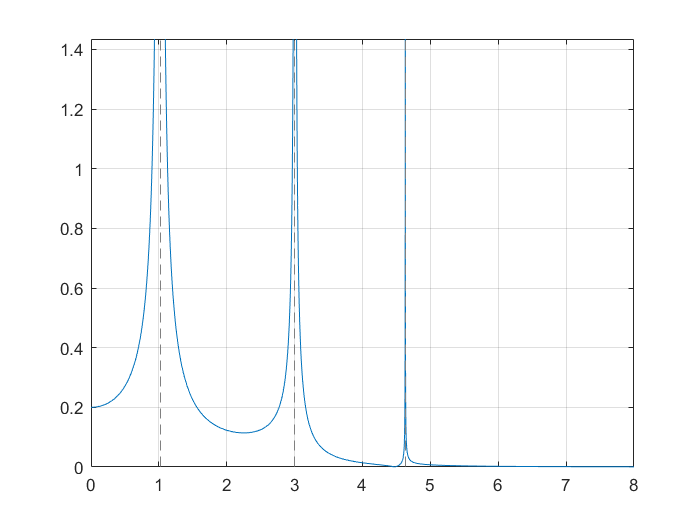

i = 3

j = 1

i = 3

j = 2

i = 3

j = 3

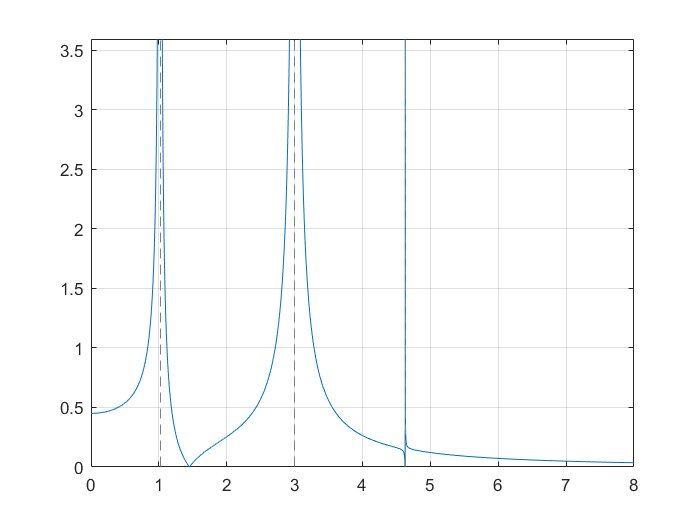

i = 1

j = 1

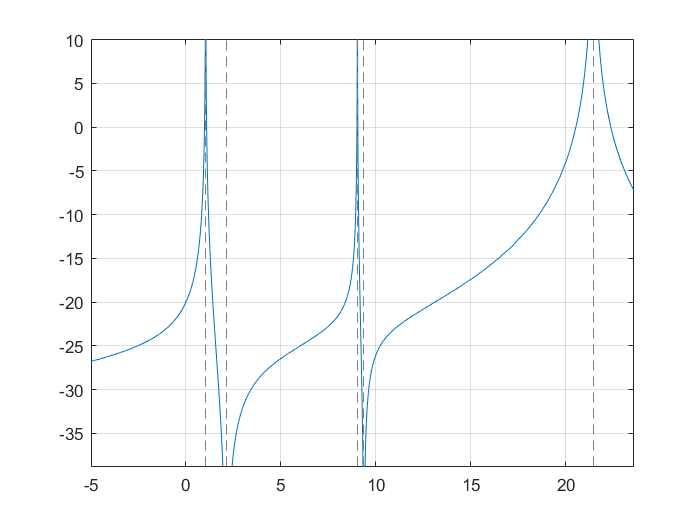

i = 1

j = 2

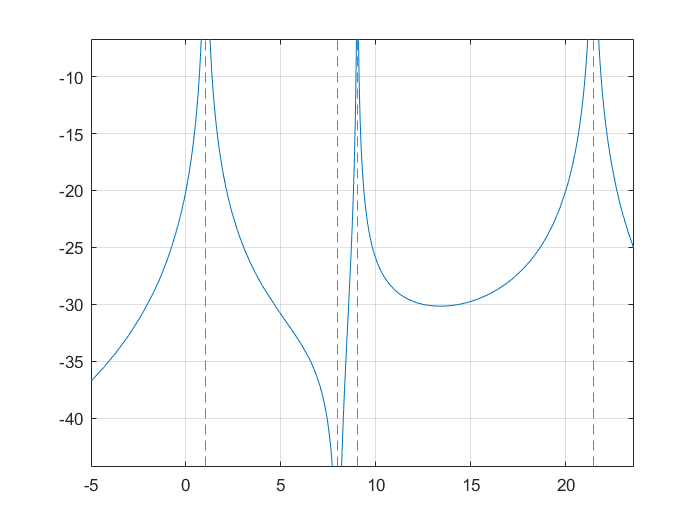

i = 1

j = 3

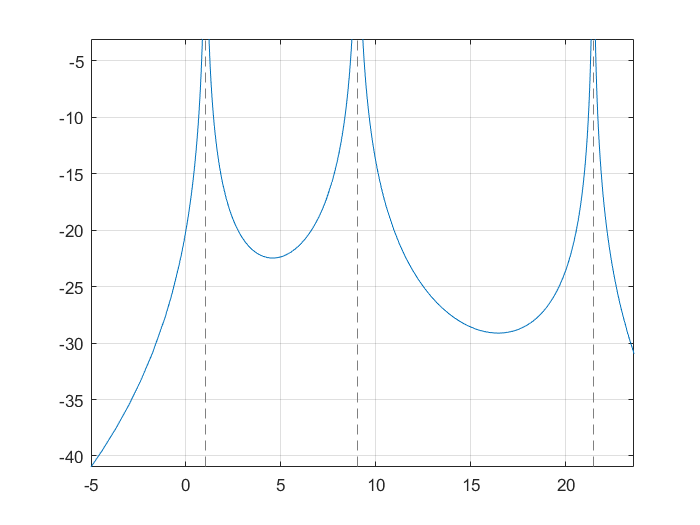

i = 2

j = 1

i = 2

j = 2

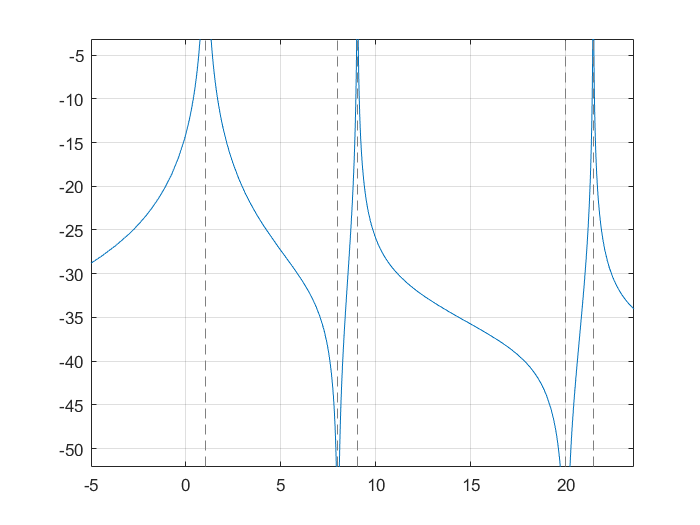

i = 2

j = 3

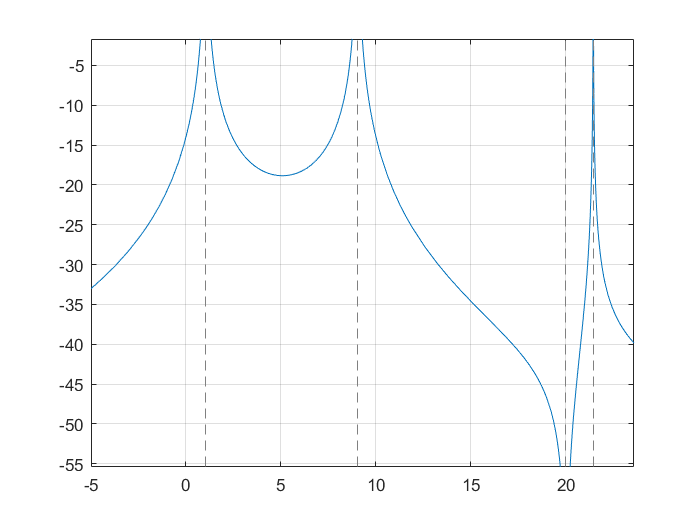

i = 3

j = 1

i = 3

j = 2

i = 3

j = 3

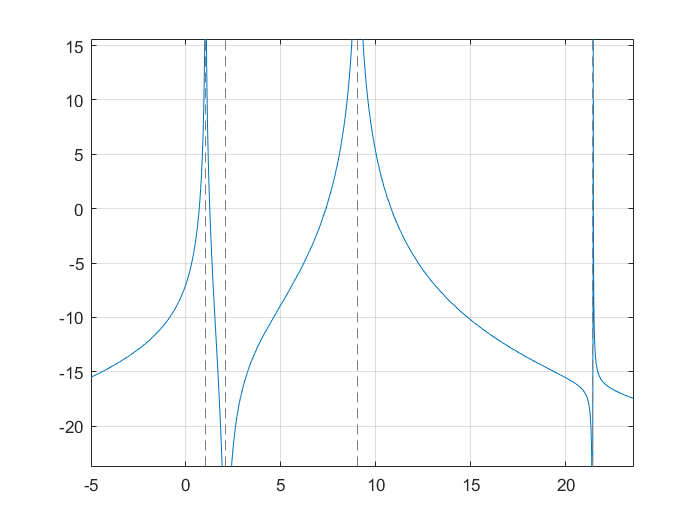

i=1;
j=1;

for i = 1:length(H)
    for j=1:length(H)
        figure()
        i
        j
        fplot(abs(H(i,j)),[0,8])
        hold on
        grid on
        hold off
        j=j+1;
    end
    i=i+1;
end

syms teta_2 M_3

teta_2=H(2,3)*M_3

$$teta\_2 = \frac{4.0\,M_{3}\,\left(w^{2}-20.0\right)}{2.0\,w^{6}-63.0\,w^{4}+450.0\,w^{2}-400.0}$$


subs(teta_2,1)

$$ans = 6.9090909090909090909090909090909\,M_{3}$$

subs(teta_2,3)

$$ans = -8.8\,M_{3}$$

subs(teta_2,4.6)

$$ans = -0.033775174733373780925775045364145\,M_{3}$$